clc;
clear all;
Nx = 100; Ny = 50; 
Lx = 100; Ly = 50; 
dx = Lx/Nx; dy = Ly/Ny;
[x, y] = meshgrid(linspace(dx,Lx,Nx), linspace(dy,Ly,Ny));

Vmax = 2;
rho_max = 10;
CFL = 0.4;
obstacle = false(Ny, Nx);
obstacle(10:30,40:60) = true;

% Domain setup;
rho = 0 * ones(Ny, Nx);
% === Plot ===
figure;
contourf(rho, 20, 'LineColor', 'none');

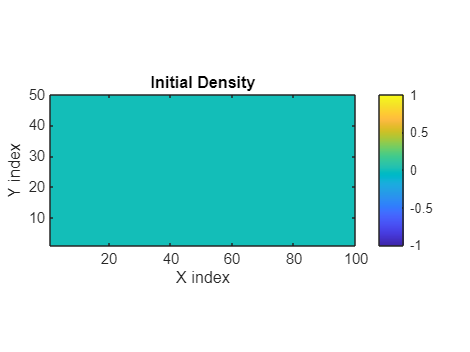

colorbar;
axis equal tight;
xlabel('X index');
ylabel('Y index');
title('Initial Density');

3

ans = 3


Tfinal = 200; 
t = 0; 
while t < Tfinal 
 % Speed field 
 f = Vmax*(1 - rho/rho_max); 
 % To speed doesn't become zero completely 
 f(f<1e-6) = 1e-6; 
 % Solve eikonal equation 
 phi = fast_sweeping(1./f,rho,dy,dx,Nx,Ny,obstacle);
 % Direction field 
 [phix, phiy] = gradient_phi(phi, dx, dy,Nx,Ny,obstacle); 
 grad_mag = sqrt(phix.^2 + phiy.^2) + 1e-12; 
 dirx = -phix ./ grad_mag; 
 diry = -phiy ./ grad_mag; 
 % Velocity field 
 vx = f .* dirx;
 vy = f .* diry; 
 % Time step 
 maxspeed = max(max(sqrt(vx.^2 + vy.^2))); 
 dt = CFL * min(dx,dy) / maxspeed; 
 if t+dt > Tfinal, dt = Tfinal-t; end 
 % Update rho 
 rho = upwind_update(t,rho, vx, vy, dx, dy, dt,rho_max,obstacle);

 % Advance time 
 t = t + dt;
 % Plots 
 if mod(round(t/dt),2) == 0 
 % Density (phi) 
 figure(1); 
 contourf(x, y, rho, 20, 'LineColor', 'none'); 
 colorbar; 
 caxis([0 rho_max]); 
 title(sprintf('Density \\rho at t = %.2f', t)); 
 xlabel('x'); ylabel('y'); 
 axis equal tight; 
 % Potential (phi) 
 figure(2);
 contour(x, y, phi, 100, 'LineColor', 'none'); 
 colorbar; title(sprintf('\\phi at t = %.2f',t)); 
 xlabel('x'); ylabel('y'); 
 axis equal tight; 
 % Velocity field 
 figure(3); 
 quiver(x, y, vx, vy, 1, 'k'); 
 title(sprintf('Velocity Field at t = %.2f',t)); 
 xlabel('x'); ylabel('y'); 
 axis equal tight;
 % Density Surface
 figure(4);
 surf(x, y, rho, 'EdgeColor', 'black', 'FaceColor', 'none');
 view(45+90, 30);
 title(sprintf("Density Surface \\rho at t=%.2f",t));
 xlabel('x'); ylabel('y');
 zlim([0 rho_max]);
 % Velocity Surface
 figure(5);
 surf(x, y, f, 'EdgeColor', 'black', 'FaceColor', 'none');
 view(45+90, 30);
 title(sprintf("Velocity Surface \\v at t=%.2f",t));
 xlabel('x'); ylabel('y');
 zlim([0 Vmax]);
 drawnow;
 end 
end

%This function will calculate the flux at the right boundary when needed.
function flux = flux_value(t)
 if t>=0 && t<=60
 flux = t/12;
 elseif t>=60 && t<=120
 flux = 10 - (t/12);
 elseif t>=120
 flux = 0;
 end
end
function [phix,phiy] = gradient_phi(phi,dx,dy,Nx,Ny,obstacle)
 phix = zeros(Ny,Nx);
 phiy = zeros(Ny,Nx);
 % Top Boundary
 for i=2:Nx-1
 phix(Ny,i) = (phi(Ny,i+1) - phi(Ny,i-1))/(2*dx);
 phiy(Ny,i) = (phi(Ny,i) - phi(Ny-1,i))/dy;
 end
 % Bottom Boundary
 for i=2:Nx-1
 phix(1,i) = (phi(1,i+1) - phi(1,i-1))/(2*dx);
 phiy(1,i) = (phi(2,i) - phi(1,i))/dy;
 end
 % Left Boundary

 for j = 2:Ny-1
 phix(j,1) = (phi(j,2) - phi(j,1))/dx;
 phiy(j,1) = (phi(j+1,1) - phi(j-1,1))/(2*dy);
 end
 % Right Boundary
 for j = 2:Ny-1
 phix(j,Nx) = (phi(j,Nx) - phi(j,Nx-1))/dx;
 phiy(j,1) = (phi(j+1,Nx) - phi(j-1,Nx))/(2*dy);
 end
 % Interior point
 for i = 2:Nx-1
 for j = 2:Ny-1
 % If the interioir point is far from the obstacle
 if ~obstacle(j+1,i) && ~obstacle(j-1,i) && ~obstacle(j,i+1) && ~obstacle(j,i-1)
 phix(j,i) = (phi(j,i+1) - phi(j,i-1))/(2*dx);
 phiy(j,i) = (phi(j+1,i) - phi(j-1,i))/(2*dy);
 % If the interior point is at the boundary of obstacle
 else 
 if obstacle(j+1,i)
 phiy(j,i) = (phi(j,i) - phi(j-1,i))/dy;
 elseif obstacle(j-1,i)
 phiy(j,i) = (phi(j+1,i) - phi(j,i))/dy;
 end
 if obstacle(j,i+1)
 phix(j,i) = (phi(j,i) - phi(j,i-1))/dx;
 elseif obstacle(j,i-1)
 phix(j,i) = (phi(j,i+1) - phi(j,i))/dx;
 end
 end
 end
 end
 % Corners
 phix(1,1) = (phi(1,2) - phi(1,1))/dx;
 phiy(1,1) = (phi(2,1) - phi(1,1))/dy;
 phix(Ny,1) = (phi(Ny,2) - phi(Ny,1))/dx;
 phiy(Ny,1) = (phi(Ny,1) - phi(Ny-1,1))/dy;
 phix(Ny,Nx) = (phi(Ny,Nx) - phi(Ny,Nx-1))/dx;
 phiy(Ny,Nx) = (phi(Ny,Nx) - phi(Ny-1,Nx))/dy;
 phix(1,Nx) = (phi(1,Nx) - phi(1,Nx-1))/dx;
 phiy(1,Nx) = (phi(2,Nx) - phi(1,Nx))/dy;
end

function phi = fast_sweeping(invf,rho,dy, dx, Nx, Ny,obstacle)

 %---------------------------------------------
 % Initialization
 %---------------------------------------------
 phi = inf(Ny, Nx); % Initial potential field
 phi(5:20, Nx) = 0; % Exit boundary (e.g., right side)
 phi(30:45,Nx) = 0;
 % Set phi inside obstacle to Inf
 phi(obstacle) = inf;
 %---------------------------------------------
 % Fast Sweeping Iterations
 %---------------------------------------------
 for sweep = 1:20
 % === Sweep 1: i→, j→
 for i = 2:Nx-1
 for j = 2:Ny-1
 if ~obstacle(j, i)
 phi = update_phi(phi,rho, invf, i, j, dx);
 end
 end
 end
 % === Sweep 2: i←, j→
 for i = Nx-1:-1:2
 for j = 2:Ny-1
 if ~obstacle(j, i)
 phi = update_phi(phi,rho, invf, i, j, dx);
 end
 end
 end
 % === Sweep 3: i←, j←
 for i = Nx-1:-1:2
 for j = Ny-1:-1:2
 if ~obstacle(j, i)
 phi = update_phi(phi,rho, invf, i, j, dx);
 end
 end
 end
 % === Sweep 4: i→, j←
 for i = 2:Nx-1
 for j = Ny-1:-1:2
 if ~obstacle(j, i)
 phi = update_phi(phi,rho, invf, i, j, dx);
 end
 end
 end

 % Normal gradient will also be so in the case of obstacle
 phi(10:30,40) = phi(10:30,39);
 phi(10:30,60) = phi(10:30,61);
 phi(10,40:60) = phi(9,40:60) ;
 phi(30,40:60) = phi(31,40:60);
 phi(:, 1) = phi(:, 2); % Left
 
 phi(1:5,Nx) = phi(1:5,Nx-1);
 phi(5:20, Nx) = 0; % Exit boundary (e.g., right side)
 phi(21:29,Nx) = phi(21:29,Nx-1);
 phi(30:45,Nx) = 0;
 phi(46:50,Nx) = phi(46:50,Nx-1);
 phi(1, :) = phi(2, :); % Top
 phi(Ny, :) = phi(Ny-1, :); % Bottom
 end
end
% =========================================================
% Subfunction: Update one grid point using Godunov scheme
% =========================================================
function phi = update_phi(phi,rho, invf, i, j, dx)
 a = min(phi(j, i-1), phi(j, i+1)); % x-direction neighbors
 b = min(phi(j-1, i), phi(j+1, i)); % y-direction neighbors
 f = invf(j, i)*(0.002*(rho(j,i)^2)); % Local inverse speed
 if abs(a - b) >= f * dx
 phi(j, i) = min(a, b) + f * dx;
 else
 inside = 2 * (f * dx)^2 - (a - b)^2;
 if inside >= 0
 phi(j, i) = (a + b + sqrt(inside)) / 2;
 end
 end
end

function rho_new = upwind_update(t,rho, vx, vy, dx, dy, dt, rho_max,obstacle)
 [Ny, Nx] = size(rho);
 
 % ---------------------------------------------
 % Boundary Conditions (Neumann/Dirichlet mix)
 % ---------------------------------------------
 for j = 1:Ny
 rho(j,1) = 5-((25-5*flux_value(t))^0.5); % Inflow wall (Dirichlet)
 end

 rho(5:20,Nx) = rho(5:20,Nx-1);
 rho(30:45,Nx) = rho(30:45,Nx-1);
 rho(1:4,Nx) = 0;
 rho(21:29,Nx) = 0;
 rho(46:50,Nx) = 0;
 for i = 1:Nx
 rho(1,i) = 0; % Top wall
 rho(Ny,i) = 0; % Bottom wall
 end
 
 rho(obstacle) = 0; % No density in obstacle
 % ---------------------------------------------
 % Initialize flux arrays
 % ---------------------------------------------
 flux_xp = zeros(Ny, Nx);
 flux_xm = zeros(Ny, Nx);
 flux_yp = zeros(Ny, Nx);
 flux_ym = zeros(Ny, Nx);
 % Upwind Scheme 
 for j = 2:Ny-1
 for i = 2:Nx-1
 if ~obstacle(j, i)
 % x-direction fluxes
 flux_xp(j,i) = max(vx(j,i),0)*rho(j,i) + min(vx(j,i),0)*rho(j,i+1);
 flux_xm(j,i) = max(vx(j,i),0)*rho(j,i-1) + min(vx(j,i),0)*rho(j,i);
 % y-direction fluxes
 flux_yp(j,i) = max(vy(j,i),0)*rho(j,i) + min(vy(j,i),0)*rho(j+1,i);
 flux_ym(j,i) = max(vy(j,i),0)*rho(j-1,i) + min(vy(j,i),0)*rho(j,i);
 end
 end
 end
 % ---------------------------------------------
 % Update density using continuity equation
 % ---------------------------------------------
 rho_new = rho - (dt/dx)*(flux_xp - flux_xm) - (dt/dy)*(flux_yp - flux_ym);
 % ---------------------------------------------
 % Enforce bounds and obstacle exclusion
 % ---------------------------------------------
 rho_new = max(0, min(rho_max, rho_new)); % Clamp between 0 and max
end